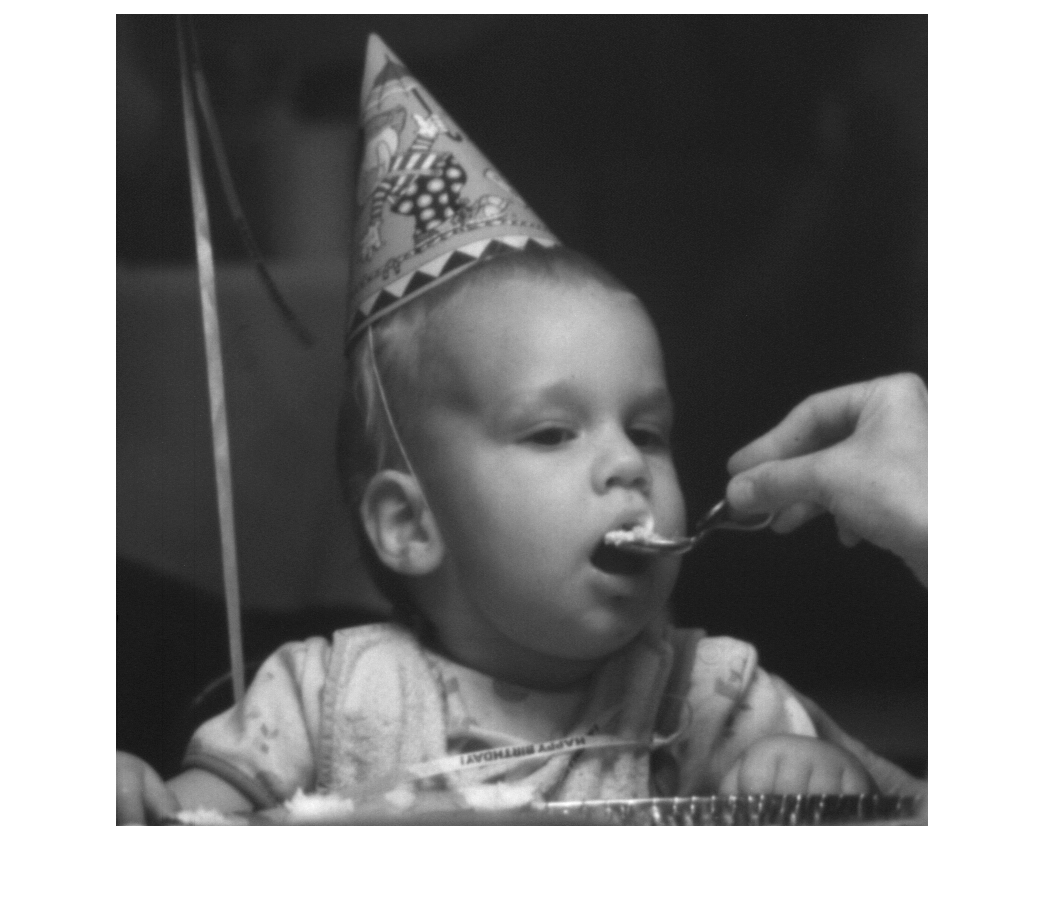

img = imread("../materials/child.tif");
[M, N] = size(img);
imshow(img, [])

H = load("../materials/H1&H2.mat").H2;

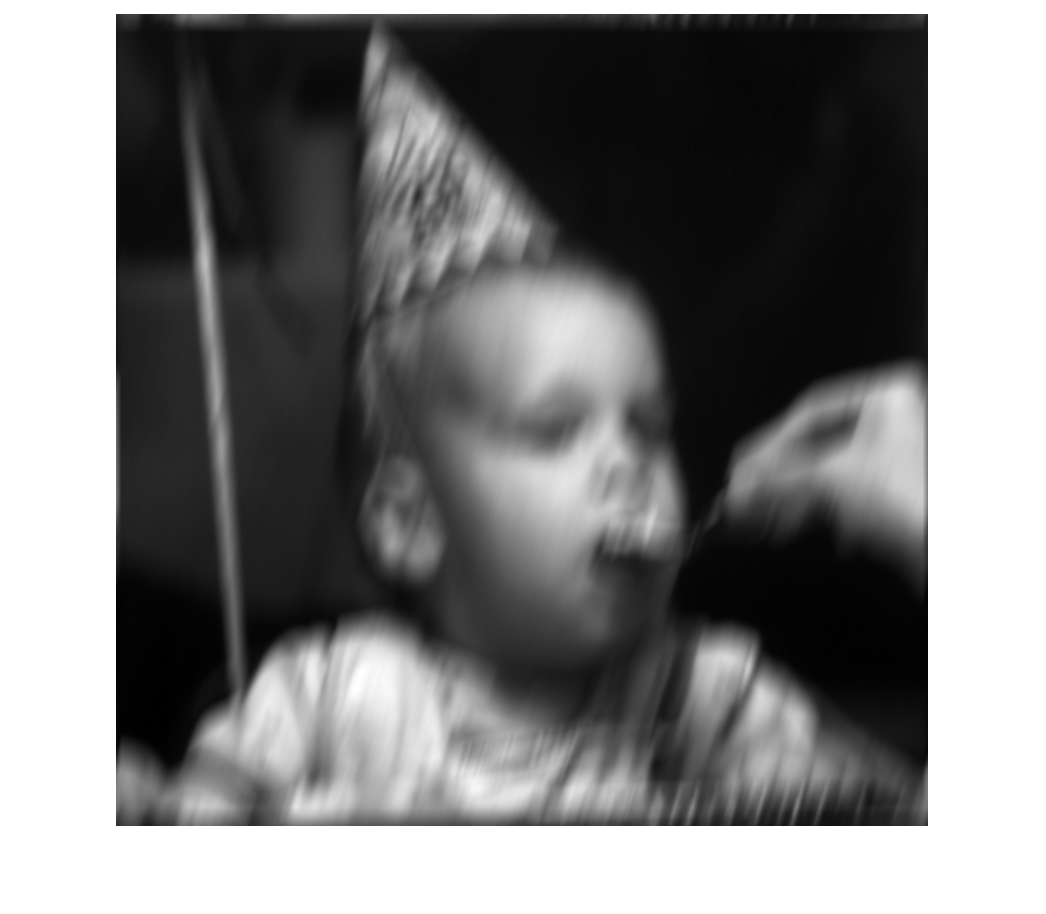

fft_img = fftshift(fft2(img));
blur_fft_img = fft_img .* H;
blur_img = ifft2(blur_fft_img);
blur_img = blur_img .* (-1).^((1:M)' + (1:N));
imshow(real(blur_img), []);

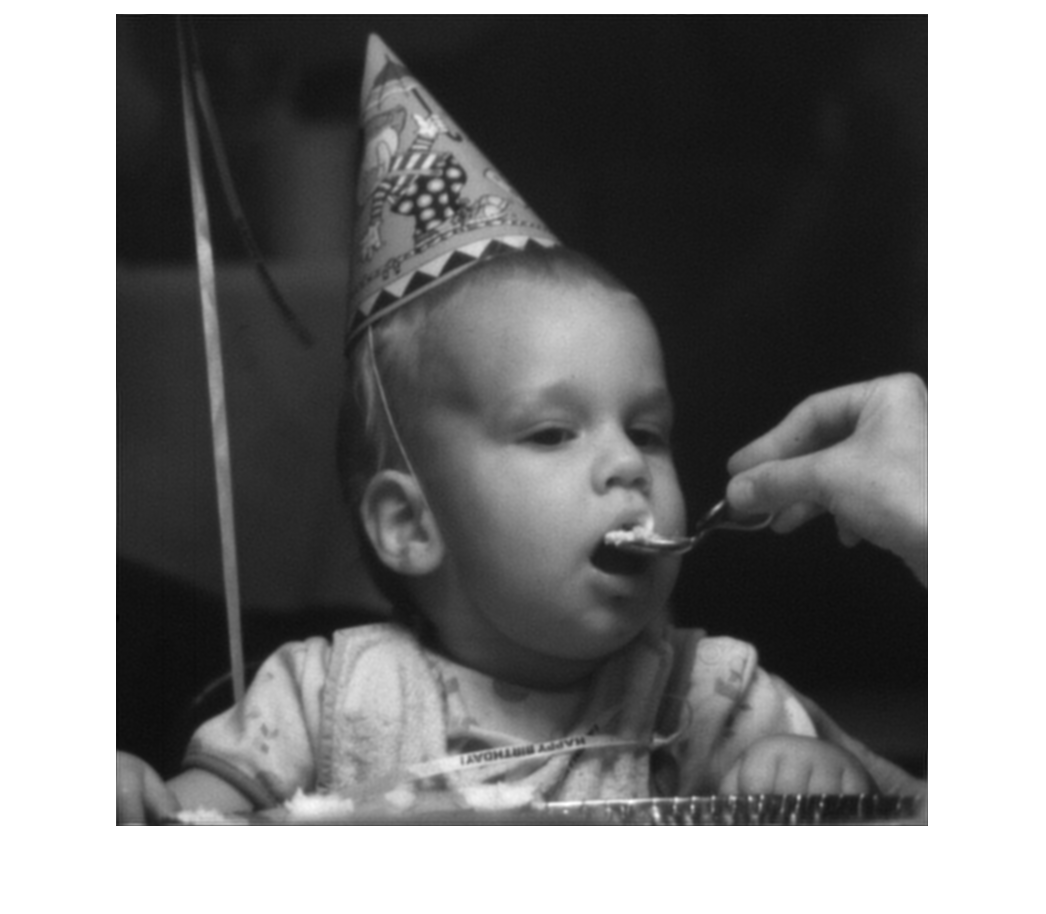

blur_fft_img = fftshift(fft2(blur_img));
r = 200;
BW_filter = zeros(size(H));
for x=1:M
    for y=1:N
        BW_filter(x, y) = 1 / (1 + (sqrt((x-M/2)^2+(y-N/2)^2)/r)^20);
    end
end
restore_fft_img = blur_fft_img ./ H .* BW_filter;
restore_img = ifft2(restore_fft_img);
restore_img = restore_img .* (-1).^((1:M)' + (1:N));
imshow(real(restore_img), [])